clear
clc
min_r = 10.741884202179357;
% min_r = 9;
sim_number = 100;
dn = zeros(sim_number,1);
n_all = zeros(sim_number,1);
for i = 1:sim_number
    n1 = round(8*rand)+1;
    m1 = round(8*rand)+1;
    m1 = 5;
    while m1 == n1
        n1 = round(8*rand)+1;
        m1 = round(8*rand)+1;
    end
    % while m1 == 5||6||2||9
    %     m1 = round(8*rand)+1
    % end
    n_all(i) = n1;
    [p,a1,a2,a3] = Minte_Carlo_randn(m1,n1);
    if isnan(p)
        disp("hahaha")
        continue
    end
    switch a1-a2

        case 0
            if max([a1,a2,a3]) == a2
                switch m1
                    case {6,7,8}
                        n = m1 + p + 1;
                        dn(i) = n - n1;
                    case {5,4,3}
                        n = m1 - p - 1;
                        dn(i) = n - n1;
                    case {2,9}
                        n = m1-1;
                        disp("m = 2 || 9,无法使得a2最大")
                end
            end
        otherwise
            if max([a1,a2,a3]) == a1
                switch m1
                    case {2,3,4}
                        n = m1 + 8 - p;
                        dn(i) = n - n1;

                    case {5,6}
                        disp("m = 5 || 6,无法使得a1最大")

                    case {7,8,9}
                        n = m1 - (8-p);
                        dn(i) = n - n1;
                end
            end
            if max([a1,a2,a3]) == a3
                switch m1
                    case {2,3,4,5}
                        n = m1 + p + 1;
                        dn(i) = n - n1;
                    case {6,7,8,9}
                        n = m1 - p - 1;
                        dn(i) = n - n1;
                end
            end
            if max([a1,a2,a3]) == a2
                switch m1
                    case {6,7,8}
                        n = m1 + p + 1;
                        dn(i) = n - n1;
                    case {5,4,3}
                        n = m1 - p - 1;
                        dn(i) = n - n1;
                    case {2,9}
                        
                        n = mod((m1+8),9);
                        dn(i) = 0;
                        disp("m = 2 || 9")
                end
            end
    end
end
n_mean = mean((n_all));
sst = sum((n_all - ones(sim_number,1)*n_mean).^2);
sse = sum(dn.^2);
R2 = 1-sse/sst

R2 =    0.960861056751468


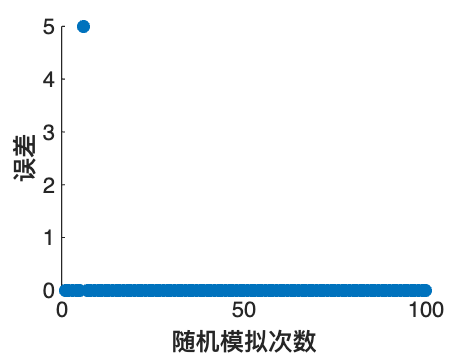

scatter(1:sim_number,dn,'filled');
xlabel("随机模拟次数");
ylabel('误差');